# Testing (scroll down and skip this for simulation loop)

Otherwise run here to simulate a uav mission

### TO DO

- parallelize digitaltwin execution, gather total flight times, create distribution. this is RUL for next true system flight

### Load paths and variables

addpath(genpath(pwd));
load_db_params;
conn = database(datasource_name, user_name, password);

% load UAV airframe
uav_sern = 'X001';
octomodel = get_airframe(conn, uav_sern);

% load battery
battery_sern = 'B001';
battery = get_battery(conn, battery_sern);
batterytwin = get_battery(conn, battery_sern);

% load motors
[Motor1, Motor2, Motor3, Motor4, Motor5, Motor6, Motor7, Motor8] = get_motors(conn, octomodel.id);
[Motortwin1, Motortwin2, Motortwin3, Motortwin4, Motortwin5, Motortwin6, Motortwin7, Motortwin8] = get_motors(conn, octomodel.id);

% load the trajectory
load_trajectory;

% load base directory
load_base_workspace;

### Simulate

Mode Selection 

- true system - nominal

- true system - degraded

- digital twin - nominal

- digital twin - degraded

%sys = "TrueSystem";
sys = "DigitalTwin";

mode = "Nominal";
%mode = "Degraded";

% degraded_level needs fixed to reflect the non-accelerated degradation
% profiles, before 11 was really degraded, now it is hardly
degraded_level = 11;

Degraded or Nominal

if mode == "Degraded"
    battery.R0=rdeg(degraded_level);
    battery.Q=qdeg(degraded_level);
    Motor2.Req=mdeg(degraded_level);
else
    battery.R0=rdeg(1);
    battery.Q=qdeg(1);
    Motor2.Req=mdeg(1);
end

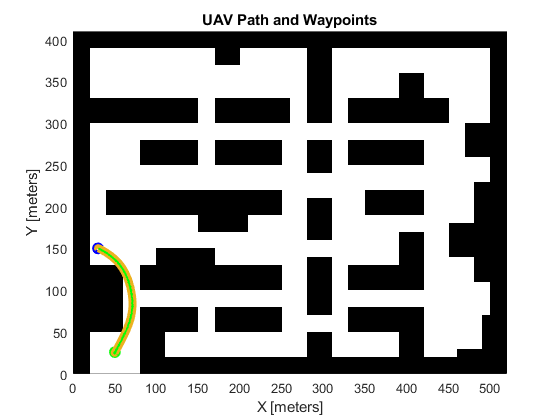

if sys == 'TrueSystem'
    octomodel.sampletime = .025;
    disp('true system simulation');
    load_system('truesystem');
    tic
    out = sim('truesystem.slx');

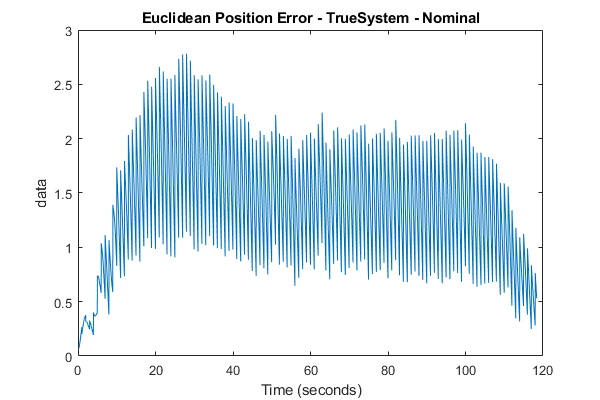

    toc
else
    octomodel.sampletime = .05;
    load_system('digitaltwin1c');
    tic

    out = sim('digitaltwin1c.slx');
    toc
end

## Write data to database

rul = flight_time.Data(end, 1)
start = datetime(now, 'ConvertFrom', 'datenum');
start = dateshift(start, 'start', 'second');
stop = start + seconds(rul*60);
mission_id = table2array(select(conn, 'select id from mission_tb mt order by id desc limit 1;'));
if isempty(mission_id)
    mission_id = 1;
else
    mission_id = mission_id + 1;
end

if sys == "TrueSystem"
    write_mission_data;
    write_battery_data;
    write_flight_data;
end

## Plot Path

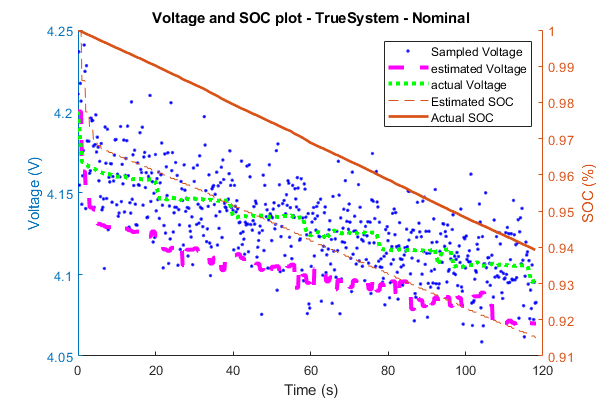

f1 = figure(1); clf;
hold on;
show(map);
plot(pos_observed.Data(1,1), pos_observed.Data(1,2), 'go', 'markerfacecolor', 'g', 'markersize', 8);

for i = 1:length(waypoints(:,1))
   plot(waypoints(i,1), waypoints(i,2), 'bo', 'LineWidth', 3); 
end
plot(xRefPoints(:,2), yRefPoints(:,2), 'linewidth', 6);
%plot(pos_actual.Data(:,1), pos_actual.Data(:,2), 'linewidth', 6);
plot(pos_observed.Data(:,1), pos_observed.Data(:,2),'g--', 'linewidth', .5);
if ~any(stop_code.Data(:,3))
    plot(pos_observed.Data(end, 1), pos_observed.Data(end, 2), 'rx', 'markersize', 9, 'LineWidth', 3);
end
hold off;
title("UAV Path and Waypoints");

## Euclidean Position Error

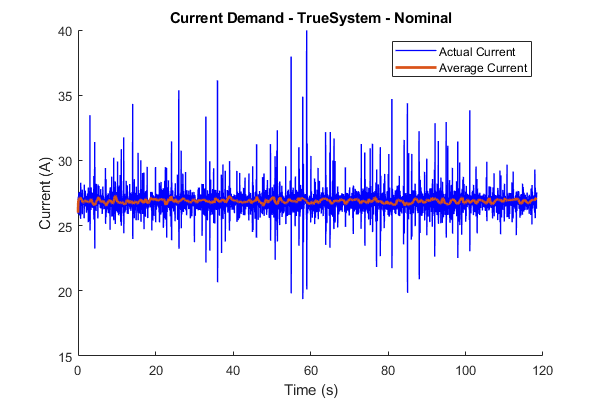

f2 = figure(2); clf;

plot(euclidean_pos_err);
ttl = sprintf("%s - %s - %s", 'Euclidean Position Error', sys, mode);
title(ttl);

## Voltage and SOC Plot

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
yyaxis left;
hold on;
plot(battery_observed.Time(:), battery_observed.Data(:,1), 'b.',  "DisplayName", "Sampled Voltage");
plot(battery_observed.Time(:), battery_observed.Data(:,2), 'm', 'linewidth', 3, "DisplayName", "estimated Voltage");
plot(battery_actual.Time(:), battery_actual.Data(:,1), 'g', 'linewidth', 3, "DisplayName", "actual Voltage");
hold off;
ylabel("Voltage (V)");
yyaxis right;
hold on;
if sys == "TrueSystem"
    plot(battery_observed.Time(:), battery_observed.Data(:,3), '--', "DisplayName", "Estimated SOC");
end

plot(battery_actual.Time(:), battery_actual.Data(:,2),'-', 'linewidth', 2, "DisplayName", "Actual SOC");
hold off;
ttl = sprintf("%s - %s - %s", 'Voltage and SOC plot', sys, mode);
title(ttl);
xlabel("Time (s)");
ylabel("SOC (%)");
legend();

## Current Plot

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
hold on;
plot(current.Time(:,1), current.Data(:,1), 'b', 'linewidth', 1, "DisplayName", "Actual Current");
plot(downsample(current.Time(:,1), 3),smoothdata(downsample(current.Data(:,1), 3), 'rlowess', 20), 'linewidth', 2, "DisplayName", "Average Current");
hold off;
title(sprintf("%s - %s - %s", 'Current Demand', sys, mode));
xlabel("Time (s)");
ylabel("Current (A)");
ylim([15 40]);
legend();

twin_ctr = 1;
times = zeros(1,4);
vs = zeros(1,4);
socs = zeros(1,4);
r0s = zeros(1,4);
qs = zeros(1,4);
ms = zeros(1,4);
errs = zeros(1,4);
degs = zeros(6,4);

times(twin_ctr) = flight_time.Data(end);
vs(twin_ctr) = battery_actual.Data(end, 1);
socs(twin_ctr) = battery_actual.Data(end, 2);
r0s(twin_ctr) = battery_actual.Data(end, 3);
qs(twin_ctr) = battery_actual.Data(end, 6);
ms(twin_ctr) = motors.Data(end, 1);
errs(twin_ctr) = mean(euclidean_pos_err);

# *********************************************************************************************************************

# Simulation Loop 

# *********************************************************************************************************************

## Start here!

## load main workspace 

addpath(genpath(pwd));
load_db_params;
conn = database(datasource_name, user_name, password);

% load UAV airframe
uav_sern = 'X001';
octomodel = get_airframe(conn, uav_sern);

% load battery
battery_sern = 'B001';
battery = get_battery(conn, battery_sern);
batterytwin = get_battery(conn, battery_sern);

% load motors
[Motor1, Motor2, Motor3, Motor4, Motor5, Motor6, Motor7, Motor8] = get_motors(conn, octomodel.id);
[Motortwin1, Motortwin2, Motortwin3, Motortwin4, Motortwin5, Motortwin6, Motortwin7, Motortwin8] = get_motors(conn, octomodel.id);

% load the trajectory
load_trajectory;

% load base directory
load_base_workspace;

## Initialize some variables

% counter for each true system simulation
true_ctr = 1;

true_ctr = 1


% for poly fitting
lookback = 6;

% how far into the future to look

Elapsed time is 34.980913 seconds.


horizon = 2;

% number of missions (can be oversized)
n_missions = 100;

% keep track of delta over time
% number of missions, 3 degradation parameters, 2 coefficients to save
% (slope & intercept)
polys = zeros(n_missions, 3, 2);

% keep track of degradation parameter values for poly fitting
q_deg = zeros(n_missions, 1);
r_deg = zeros(n_missions, 1);
m_deg = zeros(n_missions, 1);

% variance gets tighter over time, a pseudo-hack... 
r_var_vals = [.001:-.00001:.0001];
q_var_vals = [1.2:-.01:.25];
m_var_vals = [.05:-.0005:.005];

next_start = datetime(now, 'ConvertFrom', 'datenum');

## Main Loop

% loop 
% accelerated is 80
% normal is 300
% test is 3
    true_ctr = 1
%for true_ctr = 1:1
    octomodel.sampletime = true_sample_rate;
    tic
    sim('truesystem.slx');
    toc
    

###         update degradation parameters for saving

    q_deg(true_ctr) = battery.Q;
    r_deg(true_ctr) = battery.R0;
    m_deg(true_ctr) = Motor2.Req;

###         update variance

    % start at .001 -- .0001
    %r_var = battery_observed.Data(end, 6);
    % start at 1.2 -- .25
    %q_var = battery_observed.Data(end, 8);
    % start at .05 -- .005
    %m_var = motors.Data(2, 4);
    if true_ctr <= length(r_var_vals)
       r_var = r_var_vals(true_ctr);
    else
        r_var = .0001;
    end
    if true_ctr <= length(q_var_vals)
        q_var = q_var_vals(true_ctr);
    else
        q_var = .25;
    end
    if true_ctr <= length(m_var_vals)
        m_var = m_var_vals(true_ctr);
    else
        m_var = .005;
    end

### **        sample the degradation parameters and update**

    battery.R0 = normrnd(rdeg(true_ctr), r_var);

    mission_id    q_deg    q_var     r_deg     r_var    m_deg     m_var    battery_id    motor2_id    uav_id
    __________    _____    _____    _______    _____    ______    _____    __________    _________    ______

        5          15       1.2     -0.0011    0.001    0.2371    0.05         2             2          1   



    battery.Q = normrnd(qdeg(true_ctr), q_var);
    Motor2.Req = normrnd(mdeg(true_ctr), m_var);   
    
    if true_ctr > lookback
        x = ((i - (lookback-1)):1:i)';
        r_poly = polyfit(x, smoothdata(r_deg((i-(lookback-1)):i)', 'rlowess', 5), 1);
        q_poly = polyfit(x, smoothdata(q_deg((i-(lookback-1)):i)', 'rlowess', 5), 1);
        m_poly = polyfit(x, smoothdata(m_deg((i-(lookback-1)):i)', 'rlowess', 5), 1);
        
        polys(true_ctr, 1, :) = r_poly;
        polys(true_ctr, 2, :) = q_poly;
        polys(true_ctr, 3, :) = m_poly;
        
        r_mu = polyval(r_poly, true_ctr + horizon);
        q_mu = polyval(q_poly, true_ctr + horizon);
        m_mu = polyval(m_poly, true_ctr + horizon);
        batterytwin.R0 = normrnd(r_mu, r_var);
        batterytwin.Q = normrnd(q_mu, q_var);
        Motortwin2.Req = normrnd(m_mu, m_var);
    else
        batterytwin.R0 = max(abs(normrnd(rdeg(true_ctr), r_var)), .0001);
        batterytwin.Q = min(abs(normrnd(qdeg(true_ctr), q_var)), 15.5);
        Motortwin2.Req = max(abs(normrnd(mdeg(true_ctr), m_var)), .001); 
    end

Elapsed time is 16.918374 seconds.


    0.0011         0         0         0
   16.8392         0         0         0
    0.2730         0         0         0



Elapsed time is 17.006136 seconds.


    0.0011    0.0015         0         0
   16.8392   14.7293         0         0
    0.2730    0.2930         0         0



Elapsed time is 17.878899 seconds.


    0.0011    0.0015    0.0000         0
   16.8392   14.7293   15.0391         0
    0.2730    0.2930    0.2647         0



Elapsed time is 18.607350 seconds.


    0.0011    0.0015    0.0000    0.0022
   16.8392   14.7293   15.0391   16.8531
    0.2730    0.2930    0.2647    0.2414



###         write telemetry data to database

    rul = flight_time.Data(end, 1);

    1.9883    1.9892    1.9892    1.9883



    start = next_start;
    start = dateshift(start, 'start', 'second');
    stop = start + seconds(rul*60);
    next_start = stop + minutes(60);
    mission_id = table2array(select(conn, 'select id from mission_tb mt order by id desc limit 1;'));
    if isempty(mission_id)

rul is < 10 minutes. Ending experiment.


        mission_id = 1;
    else
        mission_id = mission_id + 1;
    end

    write_mission_data;
    write_battery_data;
    write_flight_data;
    write_degradation_data;

    
    clear('battery_actual', 'battery_observed', 'ctrl_err', 'current', 'current_rs', 'euclidean_pos_err', 'flight_time', 'motors', 'pos_observed', 'pos_actual', 'stop_code' );

###         define placeholder variables

        1st attempt was a matrix of where each row is a given run. this created memory problem. now just create a single vector for each, save the vector, then clear it. repeat.

    twin_ctr = 1;
    times = zeros(1,4);
    vs = zeros(1,4);
    socs = zeros(1,4);
    r0s = zeros(1,4);
    qs = zeros(1,4);
    ms = zeros(1,4);
    errs = zeros(1,4);
    degs = zeros(3,4);

###         now simulate digital twin 4 times

    octomodel.sampletime = twin_sample_rate;

###           repeat 4 times to achieve 48 samples

    for twin_ctr=1:4
        tic
        out = sim('digitaltwin1c.slx');
        toc
        %        get the output from each parallel worker
        times(twin_ctr) = flight_time.Data(end);
        vs(twin_ctr) = battery_actual.Data(end, 1);
        socs(twin_ctr) = battery_actual.Data(end, 2);
        r0s(twin_ctr) = battery_actual.Data(end, 3);
        qs(twin_ctr) = battery_actual.Data(end, 6);
        ms(twin_ctr) = motors.Data(end, 1);
        errs(twin_ctr) = mean(euclidean_pos_err);
        degs(:, twin_ctr) = [batterytwin.R0 batterytwin.Q Motortwin2.Req]';
            %sprintf("err: %f", errs(run_ctr)) 
    if true_ctr > lookback    
        disp('[INFO] true_ctr > lookback inside digital twin');
        batterytwin.R0 = normrnd(r_mu, r_var);
        batterytwin.Q = normrnd(q_mu, q_var);
        Motortwin2.Req = normrnd(m_mu, m_var);
    else
        batterytwin.R0 = max(abs(normrnd(rdeg(true_ctr), r_var)), .0001);
        batterytwin.Q = min(abs(normrnd(qdeg(true_ctr), q_var)), 15.5);
        Motortwin2.Req = max(abs(normrnd(mdeg(true_ctr), m_var)), .001); 
    end

###                  increment the counter for data concatenation

    end 

disp(times)

###         do some checks on when to stop the simulation

    if mean(times(:)) < 15
        disp('rul is < 10 minutes. Ending experiment.');
        %break;
    end
    
    if any(stop_code.Data(:,2)) == 1
        sprintf('crash on mission %d', true_ctr)
        %break;
    end
        
%end

parallel_initializer_handler(i, lookback, horizon, r_var, q_var, m_var, twin_sample_rate)

% disp(twin_flight_times(true_ctr,:))
% disp(twin_voltages(true_ctr,:))
% disp(twin_socs(true_ctr,:))
% disp(twin_r0s(true_ctr,:))
% disp(twin_qs(true_ctr,:))
% disp(twin_mot_res(true_ctr,:))
% disp(twin_pos_errs(true_ctr,:))

mean(twin_flight_times(true_ctr,:))

# END OF PROGNOSTICS CODE

# Scratch paper below

f1 = figure(1); clf;
hold on;
x_vals = 14:.01:23;
pd = fitdist(twin_flight_times_1', 'Normal');
y = pdf(pd, x_vals);
plot(x_vals, y, 'LineWidth', 2,  'DisplayName', '1st run');
pd = fitdist(twin_flight_times_2', 'Normal');
y = pdf(pd, x_vals);
plot(x_vals, y, 'LineWidth', 2,  'DisplayName', '2nd run');
pd = fitdist(twin_flight_times_3', 'Normal');
y = pdf(pd, x_vals);
plot(x_vals, y, 'LineWidth', 2, 'DisplayName', '3rd run');
% pd = fitdist(twin_flight_times_4', 'Normal');
% y = pdf(pd, x_vals);
% plot(x_vals, y, 'LineWidth', 2, 'DisplayName', '4th run');
hold off;
title("RUL plot");
xlabel("Time (S)");
ylabel("Probability");
legend();

pd = fitdist(twin_pos_errs(1,:)', 'Normal');
x_vals = 1.5:.001:2;
y = pdf(pd, x_vals);
plot(x_vals, y, 'LineWidth', 2);

pd = fitdist(twin_flight_times(1,:)', 'Normal');
x_vals = 10:.1:25;
y = pdf(pd, x_vals);
plot(x_vals, y, 'LineWidth', 2);


## Parallel Testing

- get average runtime of of iteration without parallelism

load_system('digitaltwin1c');
runs = 5;
tic
for i = 1:runs
    load_fresh_workspace;
    octomodel.sampletime = .05;
    sim("digitaltwin1c.slx");
    rul = flight_time.Data(end)
end
t2 = toc
t2/runs

Parallel testing with parameters in setup function

arg1 = .03;
%evalin('base', 'partest.m')
for i = 1:13
    in(i) = Simulink.SimulationInput('digitaltwin1c');
end

out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()load_parallel_workspace(1,2,3,4,5,6,7));

for i = 1:5
    res = out(i).res.Data(1,1)
   
end

numRuns = 6;
tic
for i = 1:numRuns
    in(i) = Simulink.SimulationInput("digitaltwin1c");
end
tic
out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()load_workspace(i, r_var, q_var, m_var));
toc


for i = 1:numRuns
    times(i) = out(i).flight_time.Data(end);
    vs(i) = out(i).battery_actual.Data(end, 1);
    socs(i) = out(i).battery_actual.Data(end, 2);
    r0s(i) = out(i).battery_actual.Data(end, 3);
    qs(i) = out(i).battery_actual.Data(end, 6);
    ms(i) = out(i).motors.Data(end, 1);
end
disp(times)
disp(r0s)
disp(socs)
disp(qs)
avg_time = sum(times)/length(times)

% n_missions = 100;
% i = 1;
% lookback = 6;
% horizon = 3;
% r_var =.0029;
% q_var = .98;
% m_var = .002;
% twin_sample_rate = .05;
% parallel_initializer_handler(i, lookback, horizon, r_var, q_var, m_var, twin_sample_rate)
evalin('base', sprintf('parallel_initializer_handler(%d, %d, %d, %f, %f, %f, %f)', 1, 6, 3, .0029, .98, .002, .05))
% t = linspace(1, n_missions, n_missions);
% yfinal = exp(-.05*t);
% plot(t,yfinal,'c*')